# Gearshift Characterization

This code aims to produce a model that enables the team to do a more precise job of construction and calibration of the gearshift for all the future prototypes.

clc
clear 
close 

## **Data inquiry** 

Here are used two function written by us. 

The second one** (readRace)** takes all the values of the race mesured by the onboard sensors, in particular each parameter is teken 1 second after the other, so the number of parameters matches the lenght of the race.

## Gear Effect

The first 3 values are just initialization to optimize the code, so the vectors are not created in the for cycle.

The for cycle converts the rpm of the pedals (RPM) in rpm of the wheel by passing the cadence to the function gearchange that separates each gear. The filter works by assuming that every drop in cadence is linked to a gear change (actually it's true) and the cycle identifies this drops.

Then it's computed torque by using a common formula of mechanics.

The variables are assigned in the following way:

- Actual velocity --> vel_lin;

- RPM based on actual velocity with gear shift effect --> RPM_bo_vel_lin;

- Input RPM pedal --> RPM;

- Fitted RPM wheel velocity --> RPM_fit;

- RPM of the wheel based on input RPM (pedals) --> RPM_wheel_bo_RPM_pedal;

- Linear velocity of the wheel based on RPM_wheel --> vel_lin_bo_RPM.

ID = 'Diego_16_09_2023_AM_2';
bike =  "cerberus";

if(strcmp(bike,"cerberus") == 1)
        wheels = 3;
        m = 105;
        [time,vel_lin,power,dist,Hrate,RPM] = readRaceCer(ID);
        [RPM_wheel_bo_RPM_pedal, N ,vel_lin_bo_RPM] = GearChangeDetectCer(RPM);
  elseif(strcmp(bike,"phoenix") == 1)
        wheels = 2;
        m = 80;
        [altitude,RPM,dist,vel_lin,power] = readRace(ID);
        [RPM_wheel_to_RPM_pedal, N ,vel_lin_bo_RPM] = GearChangeDetect(RPM);
end

## Dissipation Factor 

In order to obtain dissipation factor, we need to first find the power generated by the input pedal (RPM) and the power which is consumed in the wheel. To do so, we first need to convert the pedal RPM into the wheel RPM by means of gear shifting, then following up the relationship between linear and angular velocity we can have the linear velocity based on the RPM of the pedal. 

The next step is to calculate $P_i=\frac{\delta J_i}{\delta x_i}$ and $\tilde P_i=\frac{\delta \tilde J_i}{\delta x_i}$, both from the actual and calculated linear velocity. The final step is to find the fraction between the integral of both with respect to the distance, which is reffered to the *Dissipation Factor* $\Lambda=\frac{\int P_i \space\delta x}{\int \tilde P_i \space\delta x}$.

## Results and Plots

vel_lin_bo_RPM is the velocity of the wheel based on the RPM count. 

Line 40 basically takes the RPM of the wheel which is obtained previously and by means of $V=r\dot \theta$ and by multipliing by 3.6 we obtain velocity in terms of Km\h.

displacement = mean(abs( vel_lin - vel_lin_bo_RPM) ./ vel_lin);
fprintf("Displacement = %4.2f",displacement)

Displacement = 0.07

if(strcmp(bike,"cerberus") == 1)
         Lambda = dissFactorCalcCer(RPM_wheel_bo_RPM_pedal,vel_lin_bo_RPM,m,ID)
  elseif(strcmp(bike,"phoenix") == 1)
         Lambda = dissFactorCalc(RPM_wheel_bo_RPM_pedal,vel_lin_bo_RPM,m,ID)
end

Lambda = 0.9012

DevStandPowerReal = std(power)

DevStandPowerReal = 31.2715

meanPower = mean(power)

meanPower = 146.4068

Calculating vel_lin_bo_RPM corrected by the error between vel_lin and vel_lin_bo_RPM

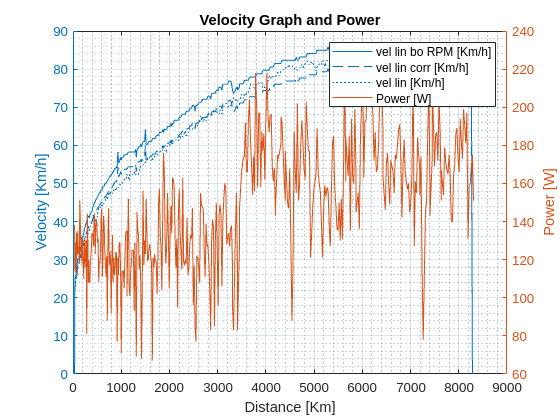

vel_lin_corr = vel_lin_bo_RPM/(1+displacement);
bike_plotter(vel_lin_bo_RPM, vel_lin_corr, dist, vel_lin,power)

max_speed_real = max(vel_lin)

max_speed_real = 84.2110

## Building the model

sys = [vel_lin,power];
nx = 1;
model = n4sid(sys,nx);

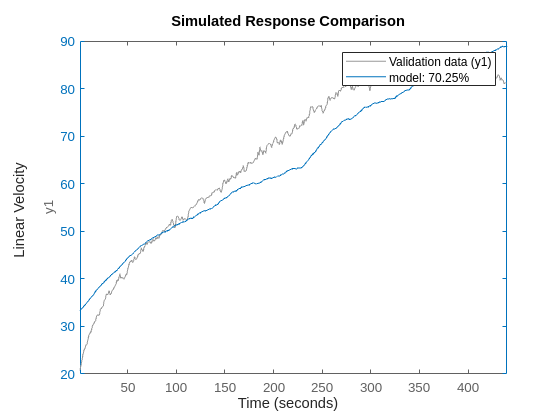

compare(sys,model);
ylabel("Linear Velocity");

## Simulation 

In this section you can simulate the run based on a mean power of your choiche. This part takes in account the oscillating power input by introducing a **Scatter factor **between **a = 85%** and **b = 115%** of the mean power. The scatter factor has beed optimized to match the standard deviation of the power input in real data, so you do not have to modify it. The only case in which is acceptable to modify it, is if the standard deviation in power of a dataset is very different from the one calculated here.

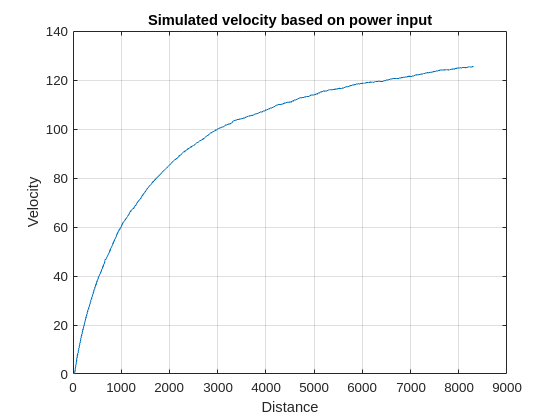

k = size(N,1);

a = 0.829;
b = 1.15;
ScatterFactor = a + (b-a)*rand(k,1);

SimPowerMean =235;

simPower = ScatterFactor*SimPowerMean;
simSpeed = sim(model,simPower);

plot(dist, simSpeed);
title("Simulated velocity based on power input");
xlabel("Distance");
ylabel("Velocity");
grid on;

MaxSimSpeed = max(simSpeed)

MaxSimSpeed = 125.5627